# Tutorial 6: Running Forward Dynamics in CASPR

Forward dynamics for cable-driven robots (CDRs) refer to the determination of the robot pose for a given set of cable forces to simulate the motion of the real robot. 

This tutorial shows how to run inverse kinematics through two approaches:

- ForwardDynamicsSimulator

- Writing your own time loop

clear;

## Setup (required for both approaches)

### Load the robot and trajectory

Load a robot as shown in `T1_load_robot.mlx `and` T2_load_trajectory.mlx`

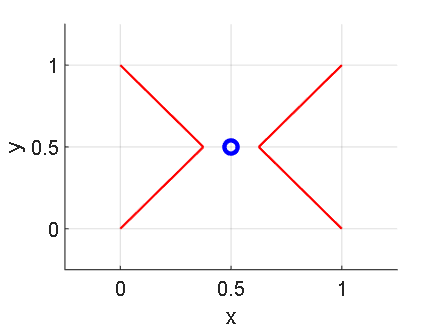

model_config = ModelConfig('Example planar XY');
cdpr_model = model_config.getModel('basic');
trajectory = model_config.getJointTrajectory('example_quintic');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot

### Run inverse dynamics for input to the forward dynamics

The steps are the same as that from `T5_inverse_dynamics.mlx`

% Setup solver
min_forces_objective = IDObjectiveMinQuadCableForce(ones(cdpr_model.numActuatorsActive,1));
id_solver = IDSolverQuadProg(cdpr_model, min_forces_objective, ID_QP_SolverType.MATLAB);
% Run inverse dynamics
id_sim = InverseDynamicsSimulator(cdpr_model, id_solver);
id_sim.run(trajectory);

[INFO] Time : 0.000000
[INFO] Time : 0.050000
[INFO] Time : 0.100000
[INFO] Time : 0.150000
[INFO] Time : 0.200000
[INFO] Time : 0.250000
[INFO] Time : 0.300000
[INFO] Time : 0.350000
[INFO] Time : 0.400000
[INFO] Time : 0.450000
[INFO] Time : 0.500000
[INFO] Time : 0.550000
[INFO] Time : 0.600000
[INFO] Time : 0.650000
[INFO] Time : 0.700000
[INFO] Time : 0.750000
[INFO] Time : 0.800000
[INFO] Time : 0.850000
[INFO] Time : 0.900000
[INFO] Time : 0.950000
[INFO] Time : 1.000000
[INFO] Time : 1.050000
[INFO] Time : 1.100000
[INFO] Time : 1.150000
[INFO] Time : 1.200000
[INFO] Time : 1.250000
[INFO] Time : 1.300000
[INFO] Time : 1.350000
[INFO] Time : 1.400000
[INFO] Time : 1.450000
[INFO] Time : 1.500000
[INFO] Time : 1.550000
[INFO] Time : 1.600000
[INFO] Time : 1.650000
[INFO] Time : 1.700000
[INFO] Time : 1.750000
[INFO] Time : 1.800000
[INFO] Time : 1.850000
[INFO] Time : 1.900000
[INFO] Time : 1.950000
[INFO] Time : 2.000000
[INFO] Time : 2.050000
[INFO] Time : 2.100000
[INFO] Time

Original joint pose (to be solved using forward dynamics):

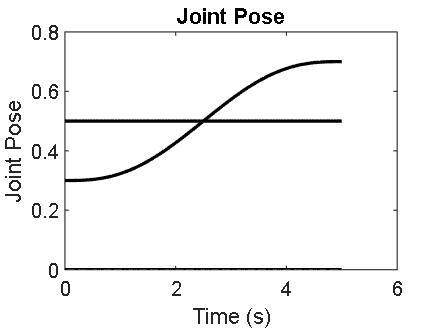

id_sim.plotJointPose();

The set of cable forces that will be the input to the forward dynamics:

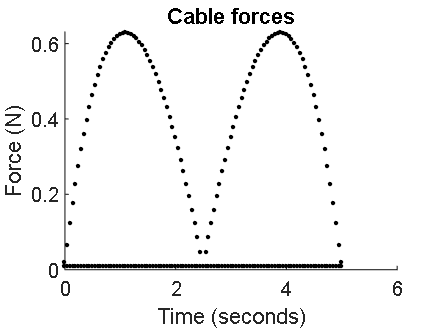

id_sim.plotCableForces();

Setup some initial values for use later:

init_q = ik_sim.trajectory.q{1}; % Initial q for the solver

Unable to resolve the name 'ik_sim.trajectory.q'.

init_q_dot = ik_sim.trajectory.q_dot{1}; % Initial q_dot for the solver

## 1) Solve using the ForwardDynamicsSimulator

The Forward`KinematicsSimulator` provides the simplest way to run a "standard" forward kinematics simulation for a defined trajectory. 

First, create the simulator object using the robot model and the specified solver:

fd_sim = ForwardDynamicsSimulator(cdpr_model, FDSolverType.ODE113);

Next, run the simulator on the resulting cable lengths and cable lengths velocity over the specified time points with the initial joint pose and velocity:

fd_sim.run(id_sim.cableForces, id_sim.cableIndicesActive, id_sim.timeVector, init_q, init_q_dot);

The forward dynamics simulator can plot the resulting joint pose

fd_sim.plotJointPose();

## 2) Writing your own time loop

If you want more control over what is happening or customise the inner-workings during the simulation, it is recommended for you to write your own time loop. The following simple example is basically what happens within the ForwardDynamics`Simulator`.

First, create the variables (pre-allocate memory) required to store the solution from the inverse kinematics (cable lengths and cable lengths velocity):

fd_solution_q = zeros(cdpr_model.numDofs, length(trajectory.timeVector)); % Each column is the solution at each time step

Setup some initial variables, previous length, previous joint pose and previous joint velocity. This is required by the forward kinematics solvers.

fd_solution_q(:, 1) = trajectory.q{1};
fd_solution_q_dot(:, 1) = trajectory.q_dot{1};
fd_solution_q_ddot(:, 1) = trajectory.q_ddot{1};

fd_solver = ForwardDynamics(FDSolverType.ODE113);

Next, loop through the trajectory as a function of time starting from index 2 since the initial pose is already known:

for t = 2:length(trajectory.timeVector)

The main step within the time loop is to call the solver to resolve the forward kinematics:

    [fd_solution_q(:,t), fd_solution_q_dot(:,t), fd_solution_q_ddot(:,t), cdpr_model] = ...
        fd_solver.compute(fd_solution_q(:, t-1), fd_solution_q_dot(:, t-1), id_sim.cableForces{t}, id_sim.cableIndicesActive{t}, zeros(cdpr_model.numDofs, 1), trajectory.timeStep, cdpr_model);
end

The results can be plotted the way you desire yourself.

figure; 
plot(trajectory.timeVector, fd_solution_q, 'LineWidth', 1.5);